;Usando observador para estimar as velocidades v e r

clear all

%constantes

m = 188.6 ; % Massa do ROV
I_z = 40.50 ; %Momento de inércia ao redor Z
m_u = 450.87; %Massa virtual na direção X
m_v = 558.92; %Massa virtual na direção Y
I_r = 239.44; %Momento virtual ao redor de Z

%coeficientes de arrasto hidrodinamico

K_u = 82.30;
K_uu = 309.70;
K_v = 8.50;
K_vv = 505.45;
K_r = 18.21;
K_rr = 94.72;

%velocidades iniciais

U = 0.5;
V = 0.5;
R = 0.126;

t_ = 0:0.01:60;
dim= size( t_ );
dimT = dim(2);


Matrizes

A = [ -(K_u/m_u)-((2*abs(U)*K_uu)/m_u), ((abs(R)*m_v)/m_u), ((abs(V)*m_v)/m_u);
    -((abs(R)*m_u)/m_v), -(K_v/m_v)-((2*abs(V)*K_vv)/m_v), -((abs(U)*m_u)/m_v);
    ((m_u-m_v)*abs(V)/I_r), ((m_u-m_v)*abs(U)/I_r), -(K_r/I_r)-((2*abs(R)*K_rr)/I_r)];

B = [1/m_u, 0, 0;
     0, 1/m_v, 0;
     0, 0, 1/I_r];

C = [1,0,0];
    

D = zeros(1,3);

E = [1/m_u, 0, 0;
     0, 1/m_v, 0;
     0, 0, 1/I_r]; %entrada de disturbio

Controlador por LQR

Q = diag([11000,10000,3500]);
R_ = diag([0.01,0.02,0.05]);


K = lqr(A, B, Q, R_);
F = (A-B*K);


Descretização e condições iniciais e entradas

t_ = 0:0.1:60;

x0 = [0;0;0];

w1 = zeros(size(t_));

for i = 1:1:601
     w1(i) = 5*sin(2*pi()*0.1*t_(i));
end


w2 = zeros(size(t_));

for i = 1:1:50
    w2(i) = 5*sin(2*pi()*0.1*t_(i));
end
for i = 51:1:56
    w2(i) = 5*sin(2*pi()*0.1*t_(i)) + 2000; %tubarão branco 1(m/s) 0.5s de impacto 1000kg
end
for i = 57:1:350
    w2(i) = 5*sin(2*pi()*0.1*t_(i));
end
for i = 351:1:356
    w2(i) = 5*sin(2*pi()*0.1*t_(i)) - 400; %tubarão-tigre 1(m/s) 0.5s de impacto 200kg
end
for i = 357:1:601
    w2(i) = 5*sin(2*pi()*0.1*t_(i));
end

w22 = zeros(size(t_));

for i = 1:1:50
    w22(i) = 5*sin(2*pi()*0.1*t_(i));
end
for i = 51:1:56
    w22(i) = 5*sin(2*pi()*0.1*t_(i)) - 2000; %tubarão branco 1(m/s) 0.5s de impacto 1000kg
end
for i = 57:1:350
    w22(i) = 5*sin(2*pi()*0.1*t_(i));
end
for i = 351:1:356
    w22(i) = 5*sin(2*pi()*0.1*t_(i)) + 400; %tubarão-tigre 1(m/s) 0.5s de impacto 200kg
end
for i = 357:1:601
    w22(i) = 5*sin(2*pi()*0.1*t_(i));
end

z_ = zeros(size(t_));

u_ = [w2;w1;z_];   %tubarão batendo atrás do ROV


u2_ = [w22;w1;z_];

Para o Observador por alocação

polos_obs = [-3 + 0.2 * j, -3 - 0.2 * j, -4.6];

Kaloc_obs = place(A',C',polos_obs);

Faloc_obs = A-Kaloc_obs'*C;

L = Kaloc_obs';

Sistema com x e x^

Gamma_aloc = [A-B*K, B*K;
         zeros(3,3), A-Kaloc_obs'*C];

Aa = [A, -B*K;
    L*C, (A-L*C-B*K)];

Bsis = [B; B];

Csis = [eye(6)];

Dsis = [zeros(6,3)];

x_obs = zeros(3, 1);
xch_obs = ones(3, 1);
cond_inicial = [x_obs; xch_obs];

sys1 = ss(F,B,C,D); %LQR controlador

sys2 = ss(Gamma_aloc, Bsis, Csis, Dsis); %sistema do observador de estados 

sys3 = ss(Aa, Bsis, Csis, Dsis); %Controlador dinâmico baseado no Observador

sys4 = ss(Gamma_aloc, Bsis, Csis, Dsis); %Observador aloc

y1 = lsim(sys1, u_, t_ ,x0); %controlador

y2 = lsim(sys2, u_, t_, cond_inicial); %observador

[y3, t2, xlq3] = lsim(sys3, u_, t_ ,cond_inicial); %controlador com observador
[y31, t21, xlq31] = lsim(sys3, u2_, t_ ,cond_inicial);

xlqx = xlq31(:,4) + U;
xlqy = xlq31(:,5) + V;
xlqr = xlq31(:,6) + R;
xlq_ = [xlqx,xlqy,xlqr];

Integrais para achar a posição

ulq = K*xlq_';

ulqx = ulq(1,:);
ulqy = ulq(2,:);
ulqr = ulq(3,:);

u1 = U + y1(:,1);

u3 = U + y3(:,4);
v3 = V + y3(:, 5);
r3 = R + y3(:, 6);

Psi = cumtrapz(t_, r3);

Vtx1 = u3*cos(Psi') - v3*sin(Psi');
Vty1 = u3*sin(Psi') + v3*cos(Psi');
Vtx = diag(Vtx1);
Vty = diag(Vty1);
Tjx =  cumtrapz(t_, Vtx);
Tjy =  cumtrapz(t_, Vty);

Plots

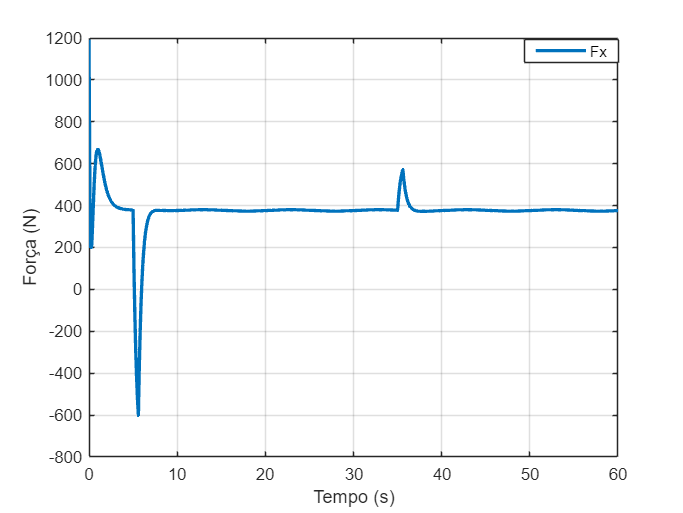

figure (1)
plot(t_, ulqx, 'LineWidth', 2)
grid on 
legend('Fx')
% title('Força de atuação em X')
xlabel('Tempo (s)')
ylabel('Força (N)')
xlim([0 60])
legend("Position", [0.76796,0.87846,0.13748,0.045761])

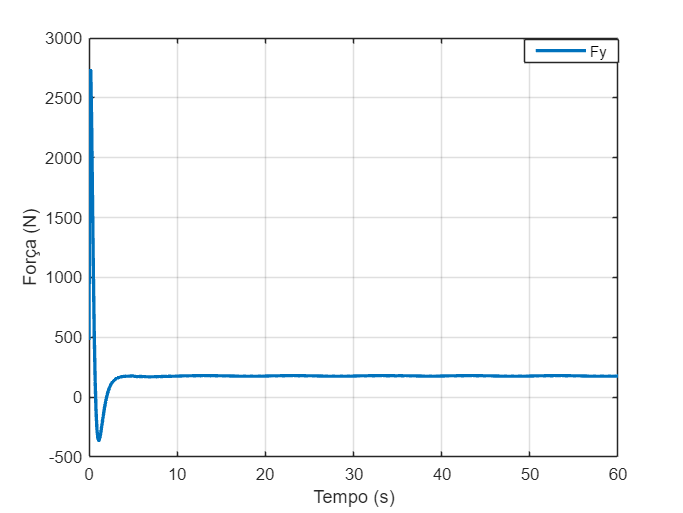


figure (1)
plot(t_, ulqy, 'LineWidth', 2)
grid on 
legend('Fy')
% title('Força de atuação em Y')
xlabel('Tempo (s)')
ylabel('Força (N)')
xlim([0 60])
legend("Position", [0.76796,0.87846,0.13748,0.045761])

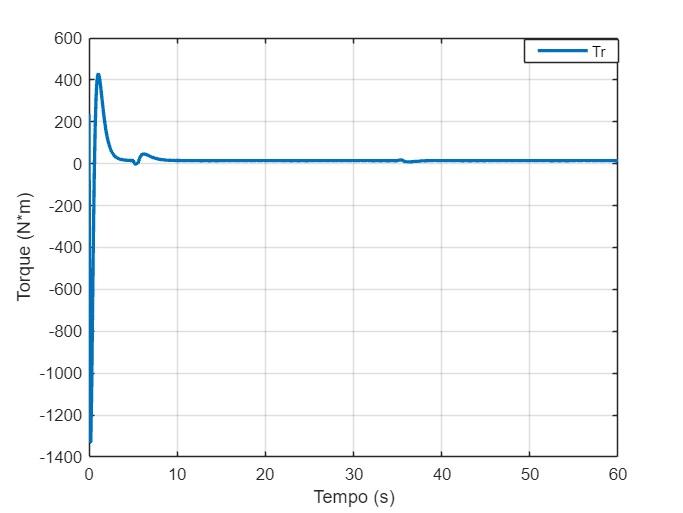


figure (1)
plot(t_, ulqr, 'LineWidth', 2)
grid on 
legend('Tr')
% title('Momento de atuação em Psi')
xlabel('Tempo (s)')
ylabel('Torque (N*m)')
xlim([0 60])
legend("Position", [0.76796,0.87846,0.13748,0.045761])

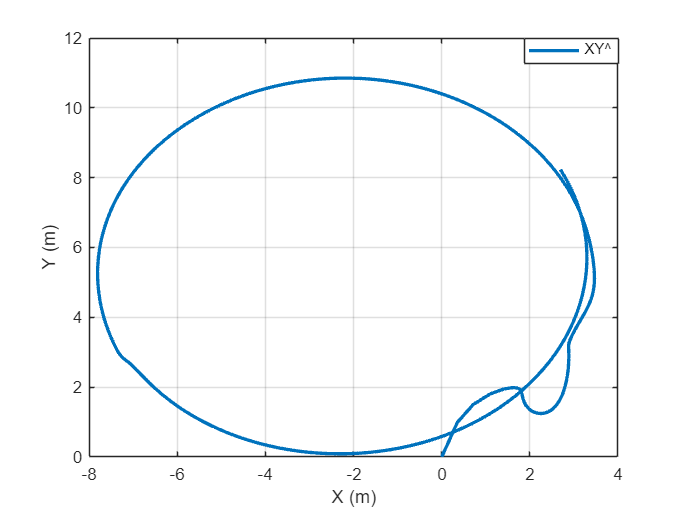



figure(1)
plot(Tjx,Tjy, 'LineWidth', 2)
grid on
% title('Trajetória no plano XY') 
xlabel('X (m)')
ylabel('Y (m)') 
legend('XY\^') 
legend("Position", [0.76796,0.87846,0.13748,0.045761])

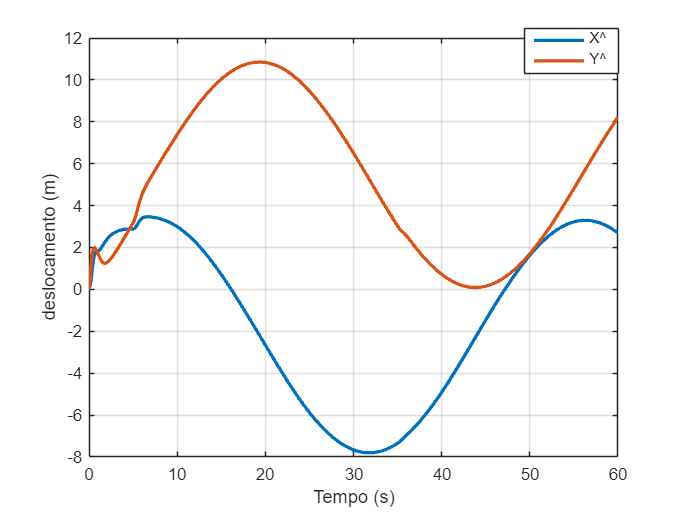


figure(2)
plot(t_,Tjx,t_,Tjy, 'LineWidth', 2)
grid on
%title('Posição em X e Y no tempo') 
xlabel('Tempo (s)')
ylabel('deslocamento (m)') 
legend('X\^','Y\^') 
legend("Position", [0.76796,0.87846,0.13748,0.045761])

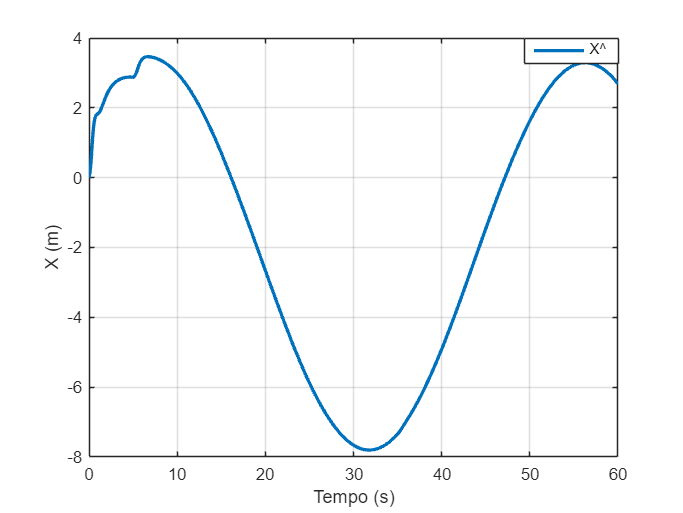


figure(2)
plot(t_,Tjx, 'LineWidth', 2)
grid on
% title('Posição em X') 
xlabel('Tempo (s)')
ylabel('X (m)') 
legend('X\^') 
legend("Position", [0.76796,0.87846,0.13748,0.045761])

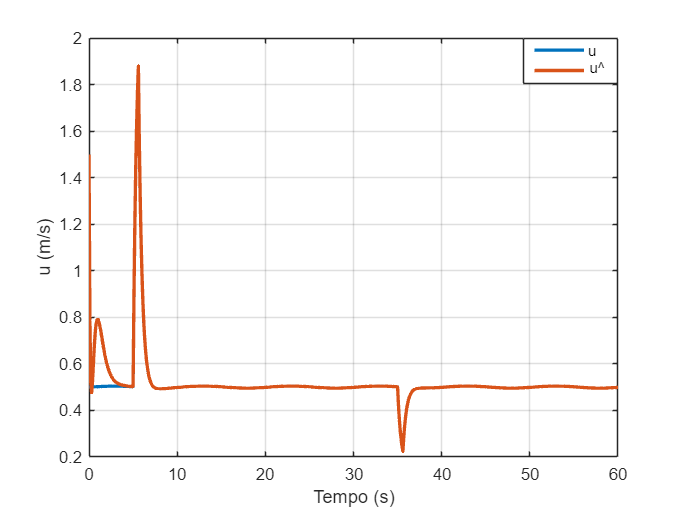



figure(3)
plot(t_, u1,t_, u3, 'LineWidth', 2)
grid on
% title('Velocidade u') 
xlabel('Tempo (s)') 
ylabel('u (m/s)')
legend('u', 'u\^')
xlim([0 60])
legend("Position", [0.76572,0.83931,0.13907,0.085501])

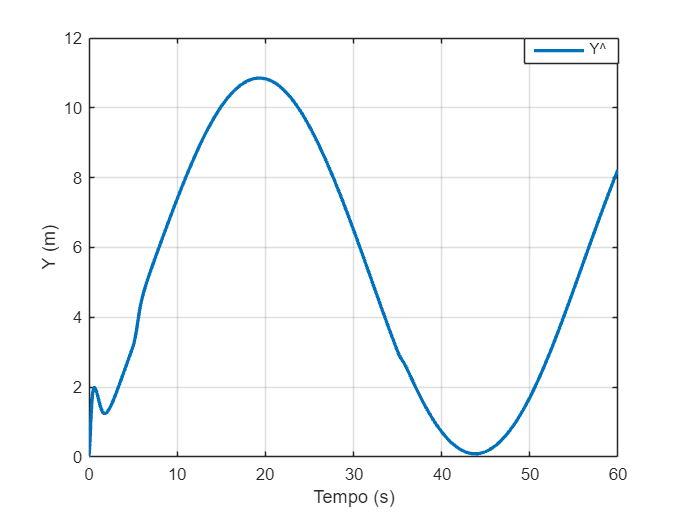



figure(4)
plot(t_,Tjy, 'LineWidth', 2)
grid on
% title('Posição em Y') 
xlabel('Tempo (s)')
ylabel('Y (m)') 
legend('Y\^') 
legend("Position", [0.76796,0.87846,0.13748,0.045761])

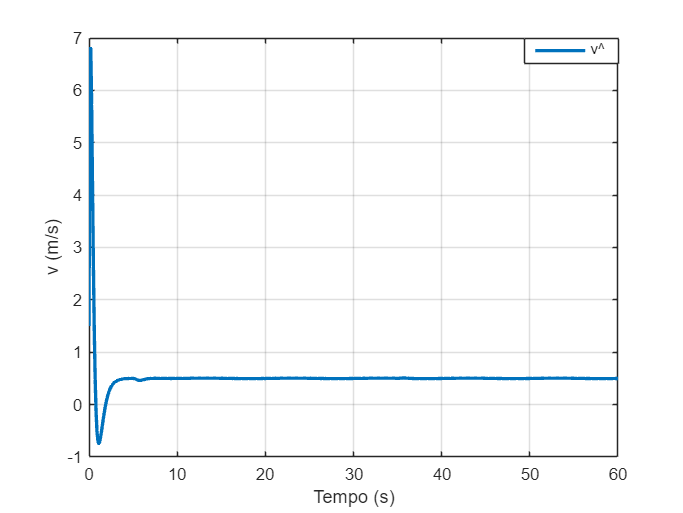



figure(5) 
plot(t_, v3, 'LineWidth', 2) 
grid on
% title('Velocidade v') 
xlabel('Tempo (s)')
ylabel('v (m/s)') 
legend('v\^') 
xlim([0 60])
legend("Position", [0.76796,0.87846,0.13748,0.045761])

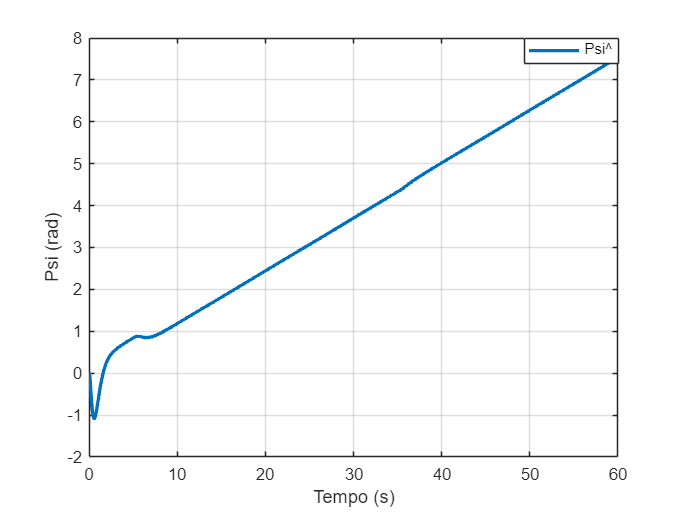



figure(6)
plot(t_,Psi, 'LineWidth', 2)
grid on
% title('Posição Psi') 
xlabel('Tempo (s)')
ylabel('Psi (rad)') 
legend('Psi\^') 
legend("Position", [0.76796,0.87846,0.13748,0.045761])

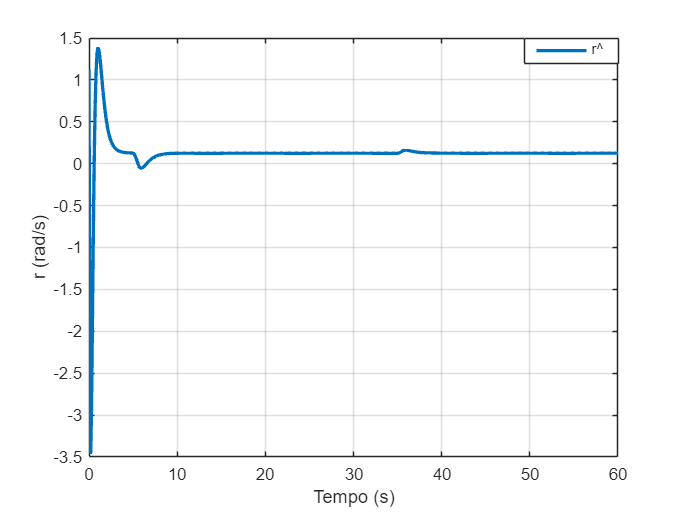




figure(7)  
plot(t_, r3, 'LineWidth', 2)
grid on 
% title('Velocidade r') 
xlabel('Tempo (s)')
ylabel('r (rad/s)') 
legend('r\^') 
xlim([0 60])
legend("Position", [0.76796,0.87846,0.13748,0.045761])